Te = 0.1;
num1 = [1];
den1 = [1 1];
numh = [1 0];
denh = [1 2];

[numd1, dend1] = c2dm(num1, den1, Te, 'zoh');
Gdd = tf(numd1, dend1, Te)


Gdd =
 
   0.09516
  ----------
  z - 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.



G2 = tf(num1, den1);
Gh = tf(numh, denh);
Gb = series(G2, Gh);
[numd2, dend2] = c2dm(Gb.Numerator{1},Gb.Denominator{1}, Te, 'zoh');
Gbd = tf(numd2, dend2, Te)


Gbd =
 
   0.08611 z - 0.08611
  ----------------------
  z^2 - 1.724 z + 0.7408
 
Sample time: 0.1 seconds
Discrete-time transfer function.



G01 = Gdd / (1 + Gbd)


G01 =
 
    0.09516 z^2 - 0.164 z + 0.0705
  ----------------------------------
  z^3 - 2.542 z^2 + 2.136 z - 0.5924
 
Sample time: 0.1 seconds
Discrete-time transfer function.


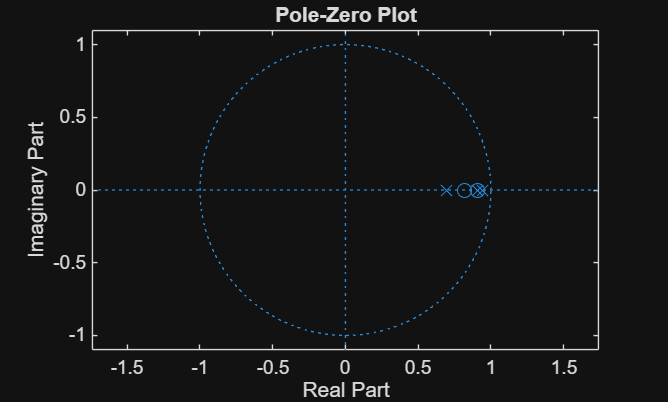

zplane(G01.Numerator{1},G01.Denominator{1})

[numd3, dend3] = c2dm(numh, denh, Te, 'zoh');
Ghd = tf(numd3, dend3, Te);

G02 = Gdd / (1 + series(Gdd, Ghd)) 


G02 =
 
    0.09516 z^2 - 0.164 z + 0.0705
  ----------------------------------
  z^3 - 2.533 z^2 + 2.119 z - 0.5842
 
Sample time: 0.1 seconds
Discrete-time transfer function.


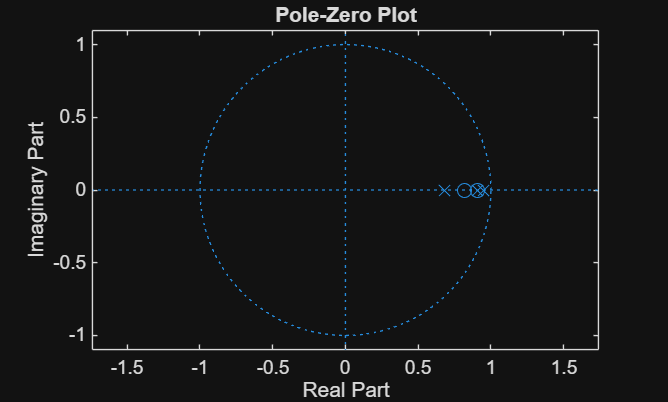

zplane(G02.Numerator{1},G02.Denominator{1})